# HW3 Team Homework SI - Modeling

## AMSC420 - Jiatong Liang and Adam Levav

## Question 1 Preprocessing Data

clear global

% Reading in the Excel file as a table then converting it into a matrix
mytable = readtable('project8_data.xlsx');
x = mytable{2:3,13:end};
x = transpose(x);

% 1st column: cumulative number of detected infections
% 2nd column: Covid-19 related deaths reported in that specific county/city

## Setting up the data

Tmax = 119;

for i = 1:size(x, 1)
    if x(i,1) >= 5
        break
    end
end
t0 = i

t0 = 52

I = zeros(120,1);

% Here we are copying over 119 ADDITIONAL days so there's 120 days in total
for j = 0:119
    I(j+1, 1) = x(t0 + j, 1);
end
I 

I =      5
     7
     7
     9
    13
    14
    17
    17
    22
    26


% Max population is pulled from Population column
Nmax = 236842

Nmax = 236842


% Nmin is maximum infected population based on our data of 120 entries.
% I believe we add one to avoid dividing by zero in certain algorithms when
% we iterate through the data
Nmin = 1 + I(120, 1)

Nmin = 2583

Here we see that the first occurrence where the number of infected is greater than 5 is on index 52 which corresponds to the day 3/13/2020.

## Problem 1 part a)

% Here we run Algorithm 1 for Nmin
N = Nmin;
% we set up the coefficient to solve for betahat
coeff = 6/(Tmax*(Tmax+1)*(2*Tmax + 1));
summation = 0;

% Because of MATLAB indexing, we want to start with I(2) and end with
% I(120) for the summation since the lecture has indexing with I(0) but in
% MATLAB that's equivalent to I(1)
% We use for loop to calculate the summation from 1 to Tmax
for t = 1:Tmax
    summation = summation + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
end
% This calculates betahat
betahat = coeff * summation

betahat = 0.0972

J = 0;

% This will calculate J(beta, N) which is stored in variable J
for t = 0:Tmax
    J = J + abs(betahat*t - log(I(t+1)/(N-I(t+1))) + log(I(1)/(N-I(1))))^2;
end

J

J = 110.0917


% Here we will plot I(t) and the SI model
% I_fctn is the function representing our predicted value of the infection
% count based on the SI model. This will be the blue line in the figure. 
figure(1)
I_fctn = @(x) (N*I(1)) / (I(1) + (N-I(1))*exp(-1*betahat*x));
fplot(I_fctn,[0 120]);

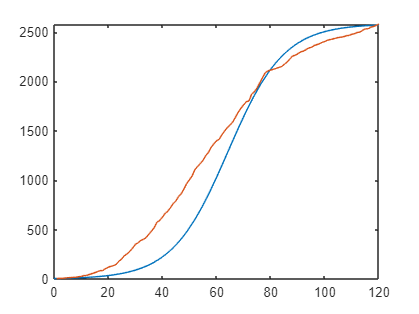

hold on
% The red line I is the true infection count
plot(I)
hold off

For this graph we would expect a very good fit. The model is assuming that every person in the population will eventually get infected and since we use 120 days worth of data, our model will attempt to fit those 120 days as close as it can hence why the two graphs look closely related.

## Problem 1 part a)

% Here we run Algorithm 1 for Nmax
N = Nmax;
% Resetting summation value
summation = 0;

% Because of MATLAB indexing, we want to start with I(2) and end with
% I(120) for the summation since the lecture has indexing with I(0) but in
% MATLAB that's equivalent to I(1)
for t = 1:Tmax
    summation = summation + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
end
% This calculates betahat
betahat = coeff * summation

betahat = 0.0721

J = 0;

% This will calculate J(beta, N)
for t = 0:Tmax
    J = J + abs(betahat*t - log(I(t+1)/(N-I(t+1))) + log(I(1)/(N-I(1))))^2;
end

% Here we display J(beta, N)
J

J = 250.7919


% Here we will plot I(t) and the SI model
% I_fctn is the function representing our predicted value of the infection
% count based on the SI model 
figure(2)
I_fctn = @(x) (N*I(1)) / (I(1) + (N-I(1))*exp(-1*betahat*x));
fplot(I_fctn,[0 120]);

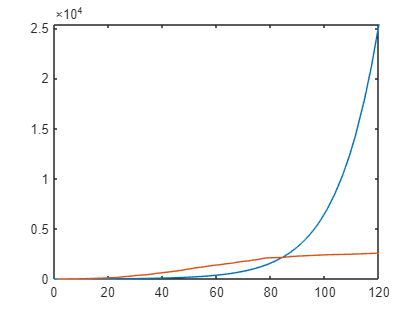

hold on
% I holds the true infection count
plot(I)
hold off

Here we see a not so good model for our true infection data and this is to be expected because the current model is assuming that every person in the population will get infected. We are using 120 days worth of data but to model a population of Nmax hence why we do not see the same end behavior as our previous graph using Nmin. Just for curiousity, we can plot the model and compare to the true infection BEYOND 120 days

figure(2)
I_fctn = @(x) (N*I(1)) / (I(1) + (N-I(1))*exp(-1*betahat*x));
fplot(I_fctn,[0 1200]);

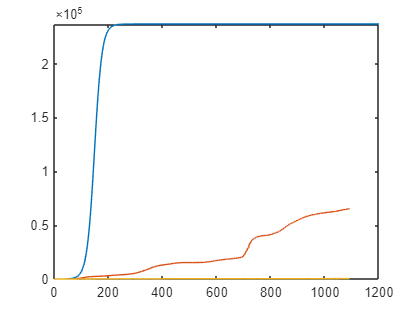

hold on
% I holds the true infection count
plot(x)
hold off

Interestingly we still see that our model is not quite good. Perhaps using 120 days of data to model a population with Nmax forces the infection rate to be very large which is why we see a very fast growing graph that labeled with the blue line. 

## Problem 1 part b) part i and ii

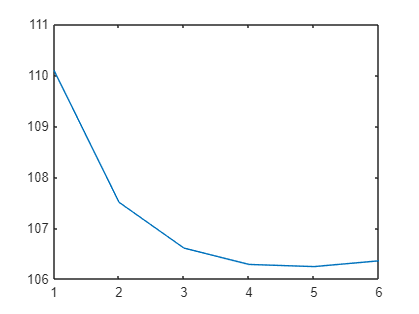

% We redefine variable J to store the values of J(N)
J = zeros(1,1);
Jold = inf;
N = 1 + I(120);
a = 6/(Tmax*(Tmax+1)*(2*Tmax + 1));

% We need to calculate the first value of J(N) before we run the while
% loop!!!
% summation1 is the first leftmost summation in the equation
summation1 = 0;
% summation2 is the second rightmost summation in the equation
summation2 = 0;
    
for t = 1:Tmax
    summation1 = summation1 + abs(log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1)))))^2;
end

for t = 1:Tmax
    summation2 = summation2 + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
end

JN = summation1 - a*(summation2^2);
J(1,1) = JN;
i = 2;

while JN < Jold
    Jold = JN;
    N = N+1;
    % We have to reset the summations everytime before we calculate
    summation1 = 0;
    summation2 = 0;
    
    for t = 1:Tmax
        summation2 = summation2 + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
    end
    
    for t = 1:Tmax
        summation1 = summation1 + abs(log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1)))))^2;
    end

    JN = summation1 - a*(summation2^2);
    J(i,1) = JN;
    i = i + 1;
end

summation = 0;
for t = 1:Tmax
    summation = summation + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
end

% Here we plot the graph of J(N)
figure(3)
plot(J);


% Here we print the estimates N and betahat
N

N = 2588

betahat = a*summation

betahat = 0.0965


JBN = 0;
% This will calculate J(beta, N)
for t = 0:Tmax
    JBN = JBN + abs(betahat*t - log(I(t+1)/(N-I(t+1))) + log(I(1)/(N-I(1))))^2;
end
% Here we print the value of the objective function
JBN

JBN = 106.3566

## Problem 1 part b) part iii


% I_fctn is the function representing our predicted value of the infection
% count based on the SI model 
figure(4)
I_fctn = @(x) (N*I(1)) / (I(1) + (N-I(1))*exp(-1*betahat*x));
fplot(I_fctn,[0 120]);

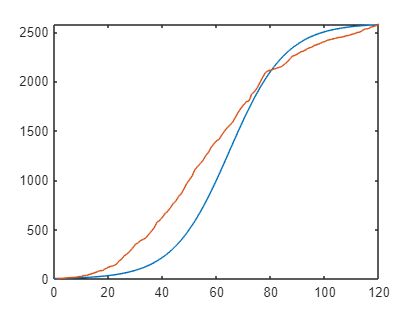

hold on
% I holds the true infection count
plot(I)
hold off

## Problem 1 part b) part iv

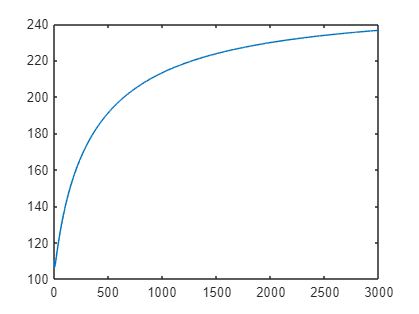

J = zeros(1,1);
i = 1;
N = Nmin;
JN = 0;

% Here we run through Nmin to Nmax
while N < Nmax
    summation1 = 0;
    summation2 = 0;
    
    for t = 1:Tmax
        summation2 = summation2 + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
    end
    
    for t = 1:Tmax
        summation1 = summation1 + abs(log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1)))))^2;
    end

    JN = summation1 - a*(summation2^2);
    J(i,1) = JN;
    i = i + 1;
    N = N + 1;
end

figure(5)
% We plot the first 3000 points or else we get overwhelmed by Nmax points
plot((1:3000), J(1:3000))

% Here we find the global minimunm
min(J)

ans = 106.2431

index = find(J == min(J));
Nmin + index - 1

ans = 2587

Here we see that on the graph the global minimum occurs immediately at the start of the graph and the values of J(N) simply just increases as the x axis increases. This result matches up with b.ii) which tells us the best N value is 2588. We will expain later in part c) why we keep seeing the value of about 2588.

## Problem 1 part c

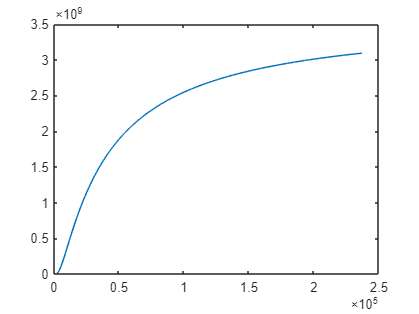

% Here we store values for the ideal objective function
ideal_I = zeros(1,1);
i = 1;
N = Nmin;

% Running from Nmin to Nmax
while N < Nmax
    %% First we need to calculate betahat for each N
    summation = 0;
    X(i) = N;
    % Because of MATLAB indexing, we want to start with I(2) and end with
    % I(120) for the summation since the lecture has indexing with I(0) but in
    % MATLAB that's equivalent to I(1)
    for t = 1:Tmax
        summation = summation + t*log((I(t+1)/I(1)) * ((N-I(1))/(N-I(t+1))));
    end
    % This calculates betahat
    betahat = coeff * summation;
    
    % Reset summation value
    summation = 0;
    for t = 0:Tmax
        summation = summation + abs(I(t+1) - (N*I(1))/(I(1) + (N-I(1))*exp(-1*betahat*t)))^2;
    end

    ideal_I(i,1) = summation;
    i = i + 1;
    N = N + 1;
end

figure(6)
plot(X, ideal_I)

min(ideal_I)

ans = 7.5282e+06

index = find(ideal_I == min(ideal_I));
Nmin + index

ans = 2584

Here we see that on the graph the global minimum occurs immediately at the start of the graph and the values of I(N, beta(N)) simply just increases as the values of N increase. This result matches up with b.ii) and with b.iv) which tells us the best N was 2588 but here we got something very close which was 2584. The reason why we see this value for our population N is because perhaps in the true infection data beyond the 120 days that we stored, the infections might have leveled off or reached a stable level before the next wave of infection hit. So the best way to minimize the objective functions is to model those 120 days exactly instead of trying to fit trends beyond the 120 days. Below we will also plot the entire true infection data just to visualize it.

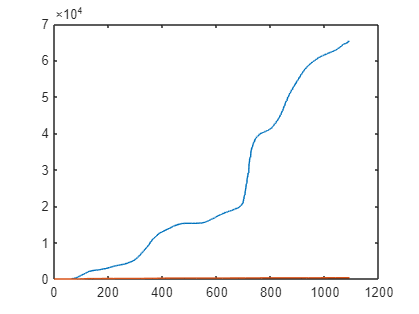

plot(x)

## Problem 2 Part 1

Create the rates of active infection I(t) using a difference formula: I(t) = v(t + t0 + τ ) − v(t + t0 − τ ), for 0 ≤ t ≤ Tmax. The parameter τ is related to incubation and infection period. Set τ = 7 days for now (the assumption is that the infection lasts up to 14 days). Plot I = I(t), the rates of active infection.

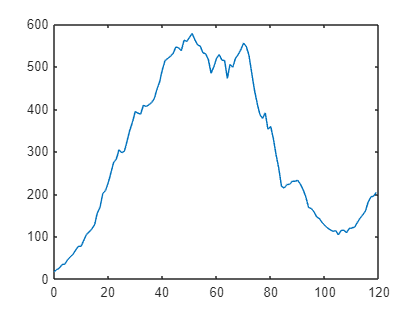

v = x(:,1); % cumulative number of infections
tau = 7;    % parameter related to incubation and infection period
% t0 calculated above: t0 = 52
% Tmax defined above: Tmax = 119

I = zeros(Tmax+1,1); % note that I(t) represent the value of I at t+1
for t=0:Tmax
    I(t+1) = v(t+t0+tau) - v(t+t0-tau);
end
I;

figure
plot(0:Tmax, I)

## Problem 2 Part 2

Implement an Euler scheme for solving the SIR Model with step size h = 0.01. Denote by (Ssim(t), Isim(t), Rsim(t)) the numerical solution. Use initialization S(0) = N , I(0) from the data set, R(0) = 0. For this problem, the unknown parameters are α, β, N .

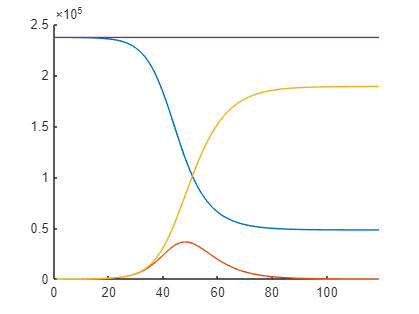

% See appendix for euler_scheme function

% Test the euler scheme
[Stest, Itest, Rtest] = euler_scheme(I(1), Tmax, 0.2, 0.4, Nmax);

figure
hold on
plot(Stest)
plot(Itest)
plot(Rtest)
fplot(Nmax)
xlim([0, Tmax])
hold off

% Compute set omega of possible values for (alpha, beta, N):
alphaSet = [1/10, 1/9, 1/8, 1/7, 1/6, 1/5];
% The final value is cut off in the PDF; I assume it's 1.6
R0Set = [0.8, 0.9, 0.95, 1, 1.05, 1.1, 1.15, 1.2, 1.3, 1.4, 1.5, 1.6];
NfracSet = 0.1:0.1:1;
Nmax = 236842; % County population; copied from data set

alphaLen = length(alphaSet);
betaLen = length(R0Set);
NLen = length(NfracSet);
%[alphaLen, betaLen, NLen]

%omega = zeros(alphaLen*betaLen*NLen,3)
omega = zeros(alphaLen, betaLen, NLen, 3);
for alphaInd = 1:alphaLen
    for R0Ind = 1:betaLen
        for NfracInd = 1:NLen
            alpha = alphaSet(alphaInd);
            beta = alpha * R0Set(R0Ind);
            N = Nmax * NfracSet(NfracInd);
            
            %omegaInd = sub2ind(length(omega), alphaInd, R0Ind, NfracInd);
            %omega(omegaInd) = [alpha, beta, N];
            omega(alphaInd, R0Ind, NfracInd, :) = [alpha, beta, N];
        end
    end
end
omega;

## Problem 2 Part 3

% J(alphaInd, betaInd, NInd) contains the L2 norm for 
% the Euler scheme with the associated params
J = zeros(alphaLen, betaLen, NLen); 
%Isims = zeros(alphaLen, betaLen, NLen, Tmax+1);

for alphaInd = 1:alphaLen
    for betaInd = 1:betaLen
        for NInd = 1:NLen
            params = num2cell(reshape(omega(alphaInd, betaInd, NInd, :), 1, []));
            [alpha, beta, N] = params{:};
            [Ssim, Isim, Rsim] = euler_scheme(I(1), Tmax, alpha, beta, N);
            l2error = norm(Isim - I, 2)^2;

            %[alpha, beta, N, l2error]
            %Isims(alphaInd, betaInd, NInd, :) = Isim;
            J(alphaInd, betaInd, NInd) = l2error;
        end
    end
end     
J;

## Problem 2 Part 4

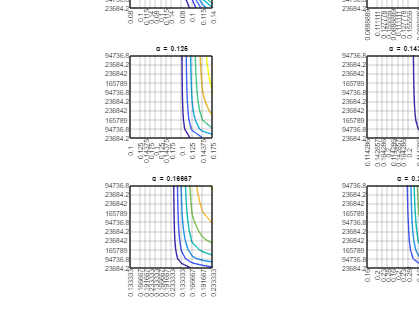

figure
tl = tiledlayout('flow');
tl.TileSpacing = 'compact';
tl.Units = 'pixels'; 
% For some reason, the resolution of the plots has become really low
% I have no idea why it changed

for alphaInd = 1:alphaLen
    nexttile

    betas = omega(alphaInd, :, :, 2);
    Ns = omega(alphaInd, :, :, 3);
    betas = reshape(betas, betaLen, []);
    Ns = reshape(Ns, [], NLen);

    values = reshape(J(alphaInd, :, :), betaLen, NLen);
    contour(betas, Ns, log(values))

    title(['\alpha = ', num2str(alphaSet(alphaInd))])
    %set(gcf,'units','pixels','position',[600,600,300,300]);

    betaTicks = betas(:,1)';
    NTicks = Ns(1,:);

    %xlim([min(betaTicks), max(betaTicks)])
    %ylim([min(NTicks), max(NTicks)])
    %xticks = betaTicks;
    %yticks = NTicks;
    
    set(gca,'XTick',betaTicks,'YTick',NTicks, ...
        'XTickLabel',betaTicks(1:3:end), ...
        'YTickLabel',NTicks(1:3:end), ...
        'FontSize',5)
    pbaspect([1 1 1]);

    %labels = string(gca().XAxis.TickLabels) % extract
    %labels(1:2:end) = nan; % remove every other one
    %gca.XAxis.TickLabels = labels; % set

    grid on
end

% Get index of minimum sum of squared residuals
[M, Ind] = min(J, [], "all");

% Find parameters at that index
%[alphaMin, betaMin, NMin] = find(J == M)
omegaTemp = reshape(omega, [], 3);
paramMin = num2cell(omegaTemp(Ind,:));
[alphaMin, betaMin, NMin] = paramMin{:};

%sympref('TypesetOutput','default');
%sprintf("$\\alpha$ = %.2f, $\\beta$ = %.2f, $N$ = %d", alphaMin, betaMin, NMin)
fprintf("alpha = %.2f, beta = %.2f, N = %g\n", alphaMin, betaMin, NMin)

alpha = 0.20, beta = 0.24, N = 23684.2


## Exercise 2 Part 1)

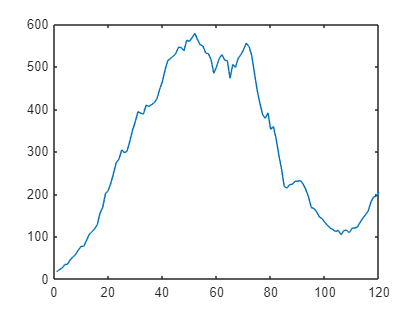


% t0 is all the way from Exercise where t0 = 52 represents the first time
% that the number of infected is greater than or equal to 5.
% vector I will store the 119 days of infection after the day t0
% tau is the incubation/infection period
I = zeros(120,1);
tau = 7;

% Here we are copying over 119 ADDITIONAL days so there's 120 days in total
for j = 0:119
    I(j+1, 1) = x(t0 + j + tau, 1) - x(t0 + j - tau, 1);
end

figure(7)
plot(I)

## Exercise 2 part 2)

Please refer to the SIR_euler.m file or the function definition for SIR_euler

## Exercise 2 part 3)

% Here we store the vectors, a for alpha, b for beta, and c for N
a = [1/10 1/9 1/8 1/7 1/6 1/5];
b = [0.8 0.9 0.95 1 1.05 1.1 1.15 1.2 1.3 1.4 1.5 1.6];
c = Nmax * [0.1 0.2 0.3 0.4 0.5 0.6 0.7 0.8 0.9 1.0];
JABN = zeros(length(a), length(b), length(c));

% Iterating through all 600 triplets
for i = 1:length(a)
    for j = 1:length(b)
        for m = 1:length(c)
            Isim = SIR_euler(a(i), b(j)*a(i), c(m), I(t0), Tmax);

            summation = 0;
            
            for t = 0:Tmax
                summation = summation + abs(I(t+1) - Isim(t+1))^2;
            end

            JABN(i,j,m) = summation;
        end
    end
end

We create a three dimensional data structure to store the values of J(alpha, beta, N)

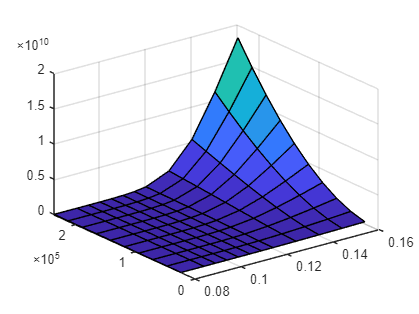

%% Exercise 2 part 4)
B = repelem(a(1)*transpose(b),[1],[10]);
C = repelem(c,[12],[1]);
% The first values of JABN will control which alpha we want to display but
% please note that the matrix for B has to be multiplied by different
% values of alpha. 
surf(B,C, squeeze(JABN(1,:,:)))

% Min function creates a matrix A and compute the smallest elements in each 
% column as well as the row indices of A in which they appear.
[M,I] = min(squeeze(JABN(1,:,:)))

M = 	1.0e+06 *

    6.1539    5.8651    5.8768    5.9429    6.0082    6.0164    5.9912    5.9729    5.9591    5.9482


I =      4     3     3     3     3     2     2     2     2     2


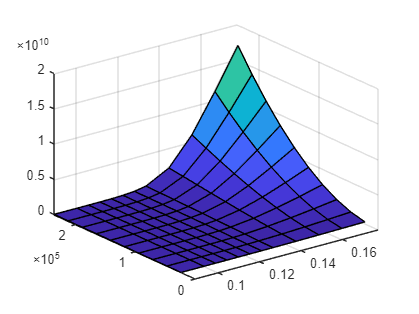

% Here we see the minimum is 5.8651 which occurs in column 2 row 3 thus the
% minimum values will be alpha = 1/10, beta = 0.1*0.95 = 0.095 and N = 0.2.
% The columns represent values of N, the rows are values of beta, and alpha
% is already determined. 

B = repelem(a(2)*transpose(b),[1],[10]);
surf(B,C, squeeze(JABN(2,:,:)))

[M,I] = min(squeeze(JABN(2,:,:)))

M = 	1.0e+06 *

    6.3022    5.9637    5.8411    5.8410    5.8686    5.9011    5.9321    5.9600    5.9847    6.0065


I =      4     3     3     3     3     3     3     3     3     3


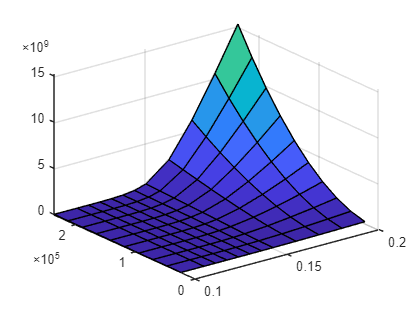

% Here we see the minimum is 5.8410 which occurs in column 4 row 3 thus the
% minimum values will be alpha = 1/9, beta = (1/9)*0.95 = 0.106 and N = 0.4.

B = repelem(a(3)*transpose(b),[1],[10]);
surf(B,C, squeeze(JABN(3,:,:)))

[M,I] = min(squeeze(JABN(3,:,:)))

M = 	1.0e+06 *

    6.7076    6.2124    5.9385    5.8461    5.8186    5.8151    5.8212    5.8311    5.8421    5.8533


I =      4     4     3     3     3     3     3     3     3     3


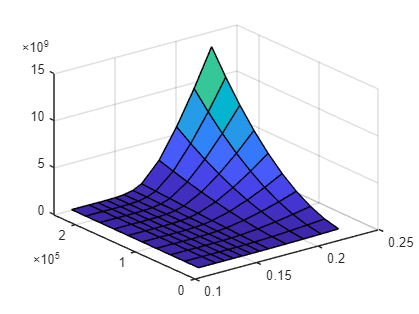

% Here we see the minimum is 5.8151 which occurs in column 6 row 3 thus the
% minimum values will be alpha = 1/8, beta = (1/8)*0.95 = 0.119 and N = 0.6.

B = repelem(a(4)*transpose(b),[1],[10]);
surf(B,C, squeeze(JABN(4,:,:)))

[M,I] = min(squeeze(JABN(4,:,:)))

M = 	1.0e+06 *

    7.3265    6.1645    6.2415    6.0259    5.9207    5.8648    5.8336    5.8156    5.8052    5.7994


I =      5     4     3     3     3     3     3     3     3     3


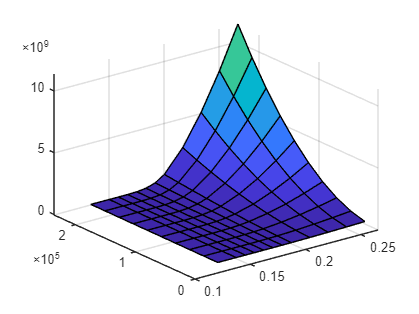

% Here we see the minimum is 5.8052 which occurs in column 9 row 3 thus the
% minimum values will be alpha = 1/7, beta = (1/7)*0.95 = 0.136 and N = 0.9.

B = repelem(a(5)*transpose(b),[1],[10]);
surf(B,C, squeeze(JABN(5,:,:)))

[M,I] = min(squeeze(JABN(5,:,:)))

M = 	1.0e+06 *

    8.3480    6.5076    6.1458    6.3107    6.2730    6.1440    6.0589    5.9998    5.9572    5.9256


I =      5     4     4     4     3     3     3     3     3     3


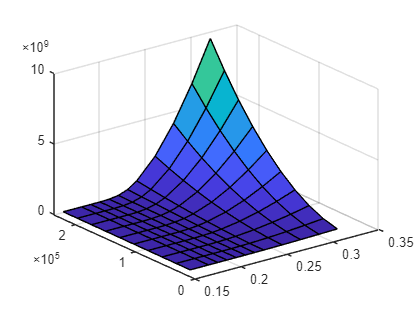

% Here we see the minimum is 5.9256 which occurs in column 10 row 3 thus the
% minimum values will be alpha = 1/6, beta = (1/6)*0.95 = 0.158 and N = 1.0.

B = repelem(a(6)*transpose(b),[1],[10]);
surf(B,C, squeeze(JABN(6,:,:)))

[M,I] = min(squeeze(JABN(6,:,:)))

M = 	1.0e+07 *

    1.0026    0.7459    0.6451    0.6161    0.6186    0.6353    0.6582    0.6525    0.6436    0.6367


I =      5     4     4     4     4     4     4     3     3     3


% Here we see the minimum is 0.6161 which occurs in column 4 row 4 thus the
% minimum values will be alpha = 1/5, beta = (1/5)*1 = 0.20 and N = 0.4.

Clearly we see that the best value was 0.6161 with alpha = 0.20, beta = 0.20, and N = 0.4 * Nmax = 94736.8

## Appendix

function [Sout, Iout, Rout] = euler_scheme(I0, Tmax, alpha, beta, N)
    h = 0.01; % step size; I assume it's measured in terms of (fractions of) days
    Nsteps = Tmax/h+1; % number of iterations

    % vectors storing the values at each step
    % the ith entry in each vector is the value at the (i-1)th time step,
    % e.g. Ssim(i) is the approximate value of S at time t = h*(i-1)
    Ssim = zeros(Nsteps,1);
    Isim = zeros(Nsteps,1);
    Rsim = zeros(Nsteps,1);
    
    % Initialization
    Ssim(1) = N;
    Isim(1) = I0;
    Rsim(1) = 0;

    % Steps
    for i = 2:Nsteps
        % t = h*(i-1);
        [Sprev, Iprev, Rprev] = deal(Ssim(i-1), Isim(i-1), Rsim(i-1));
        
        dSdt = -beta * Sprev * Iprev / N;
        dIdt =  beta * Sprev * Iprev / N - alpha * Iprev;
        dRdt = alpha * Iprev;
        %[dSdt, dIdt, dRdt]

        Ssim(i) = Sprev + dSdt * h;
        Isim(i) = Iprev + dIdt * h;
        Rsim(i) = Rprev + dRdt * h;
    end
    % We only care about the values at the day intervals 
    % (every 1/h time-steps)
    Sout = Ssim(1:(1/h):end);
    Iout = Isim(1:(1/h):end);
    Rout = Rsim(1:(1/h):end);

end